# Characteristics of the two regression tasks

(Prelimineary Analysis) **Stage 6.1**

fpath = genpath("C:\Users\regen\Documents\MATLAB\functions");
dpath = genpath("C:\Users\regen\Documents\MATLAB\Stage 6 Regression Second Try\saved data");
addpath(fpath,dpath);
load 'Stage 6 Regression Second Try'\'saved data'\regression\Tv_13_sorted.mat
load 'Stage 6 Regression Second Try'\'saved data'\regression\Tp_14_sorted.mat

To gain an initial insight: Rank features randomly and remove them in that order to determine how the number & the choice of the sensors affect prediction accuracy.

Conclusion: 

**The prediction of T_max value** is relatively unsensitive to the positioning of sensors (Clear decreasing trend of validation RMSE with increasing number of sensors, regardless which ones were chosen). Also, a high accuracy (RMSE < 0.05 ℃) can be easily achieved.

**The prediction of T_max position** is sensitive to the positioning of sensors. The inclusion of certain sensors may significantly improve the accuracy of the prediction. A high accuracy (RMSE < 1 °) is not easily achievable.

**Step to take**: Optimize the number & choice of sensors based on the performance of the second task.

rng(100)

% for T_max value prediction
numRepeats = 5;
rankings_v = zeros(numRepeats,13);
for i = 1:numRepeats
    rankings_v(i, :) = randperm(13);
end
rankings_v % display

rankings_v =      5     6     9    13    12     2     3     1    10     7     8     4    11
     1     5    12     2     7    11    13     8     4     6    10     9     3
     1     4     9    12     7     2     8     5     6     3    10    13    11
     5     6     9    10     7     1     4     3     2     8    11    13    12
     7    12     5     6     4     3     1     9     8    10     2    11    13



% for T_max position prediction
numRepeats = 5;
rankings_p = zeros(numRepeats,14);
for i = 1:numRepeats
    rankings_p(i, :) = randperm(14);
end
rankings_p % display

rankings_p =     14     8     5     7     6    13     4     3    11     2    12     1    10     9
     3    14    13    10     7     6     1     2     4    12    11     9     8     5
     6     4    11     1     2    10    14     5     7     3    12     8     9    13
     4     5     3     8    11     9    12    14    10    13     6     7     2     1
     3    13    14    10    11     7     4     6     9     5     8     2     1    12


Using fitlm(...,"quadratic","RobustOpts","off") with 10 fold cross validation

vRMSE_matrix_v = zeros(numRepeats,13); % 第j列的值代表使用j个predictor训练出的结果
vRMSE_matrix_p = zeros(numRepeats,14); % 第j列的值代表使用j个predictor训练出的结果

% for T_max value prediction
for i = 1:numRepeats
    ranking = rankings_v(i,:);
    for j = 1:13
        idx = ranking(1:j);
        [~,vRMSE,~] = train_Tv_model(Tv_13_sorted,idx);
        vRMSE_matrix_v(i,j) = vRMSE;
    end
end
vRMSE_matrix_v % display

vRMSE_matrix_v =     0.0607    0.0337    0.0250    0.0206    0.0202    0.0198    0.0191    0.0185    0.0176    0.0121    0.0064    0.0042    0.0031
    0.2814    0.0524    0.0491    0.0452    0.0262    0.0255    0.0250    0.0169    0.0147    0.0090    0.0078    0.0039    0.0031
    0.2814    0.0683    0.0408    0.0355    0.0221    0.0213    0.0152    0.0119    0.0059    0.0053    0.0049    0.0041    0.0031
    0.0607    0.0337    0.0250    0.0239    0.0158    0.0154    0.0134    0.0131    0.0133    0.0087    0.0058    0.0057    0.0031
    0.0398    0.0386    0.0276    0.0196    0.0193    0.0185    0.0158    0.0114    0.0053    0.0050    0.0049    0.0044    0.0031



% for T_max position prediction
for i = 1:numRepeats
    ranking = rankings_p(i,:);
    for j = 1:14
        idx = ranking(1:j);
        [~,vRMSE,~] = train_Tp_model(Tp_14_sorted,idx);
        vRMSE_matrix_p(i,j) = vRMSE;
    end
end
vRMSE_matrix_p % display

vRMSE_matrix_p =     1.7477    1.1063    1.0138    0.9935    0.9583    0.9265    0.6528    0.5322    0.4386    0.4136    0.4042    0.3784    0.3219    0.2294
    1.7748    1.1663    0.8590    0.5953    0.5759    0.5695    0.5593    0.5430    0.4665    0.4451    0.4371    0.3769    0.2160    0.2236
    1.7553    1.4939    0.8452    0.7185    0.7100    0.5910    0.5314    0.4473    0.4377    0.3595    0.3472    0.3309    0.2684    0.2210
    1.7734    1.6304    1.5092    0.7565    0.5497    0.3863    0.3688    0.3667    0.3332    0.3118    0.3037    0.2575    0.2240    0.2282
    1.7725    1.6079    0.8582    0.5951    0.5726    0.5576    0.4982    0.4844    0.4350    0.3709    0.3267    0.3099    0.2911    0.2214


Plot side by side

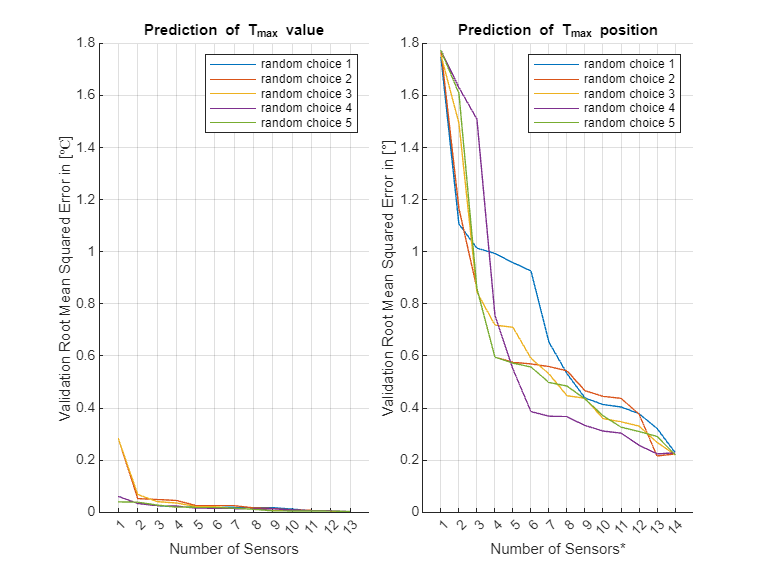

fig = tiledlayout(1,2,"TileSpacing","compact");
title(fig,"Linear Model with Quadratic and Lower Terms")

ax1 = nexttile;
hold on
for i = 1:numRepeats
    results = vRMSE_matrix_v(i,:);
    plot(1:13,results)
    xlabel("Number of Sensors")
    xticks(1:13),xlim([0,14])
    ylabel("Validation Root Mean Squared Error in [℃]")
end
legend("random choice 1","random choice 2","random choice 3",...
    "random choice 4","random choice 5")
title("Prediction of T_{max} value")
grid on, hold off

ax2 = nexttile;
hold on
for i = 1:numRepeats
    results = vRMSE_matrix_p(i,:);
    plot(1:14,results)
    xlabel("Number of Sensors*")
    xticks(1:14),xlim([0,15])
    ylabel("Validation Root Mean Squared Error in [°]")
end
legend("random choice 1","random choice 2","random choice 3",...
    "random choice 4","random choice 5")
title("Prediction of T_{max} position")
grid on, hold off

linkaxes([ax1,ax2],'y')